## Basics

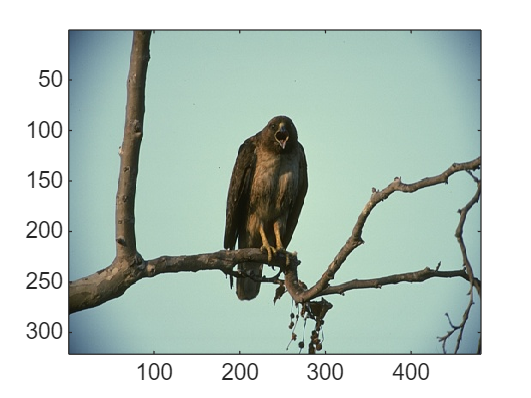

% Read an image
color_img = imread("imgs/bird.jpg");

% Display an image
image(color_img) % as a graph

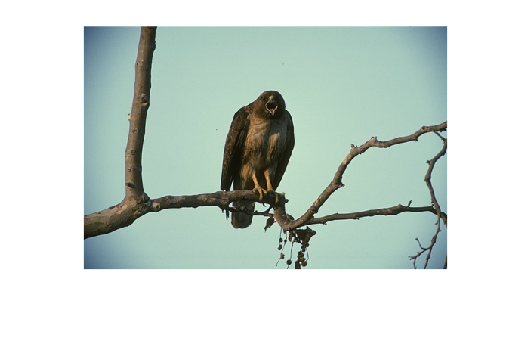

imshow(color_img); % as an image

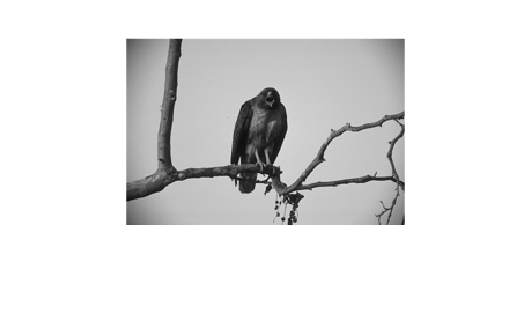

imageViewer(color_img); % in a toolbox

% Convert RGB image to grayscale
gray_img = rgb2gray(color_img);

% Resize image
gray_img_small = imresize(gray_img, 0.5);
imshow(gray_img_small);


% Save image as
imwrite(gray_img_small, "imgs/bird-small.jpg");

## Test dip_rgb2gray

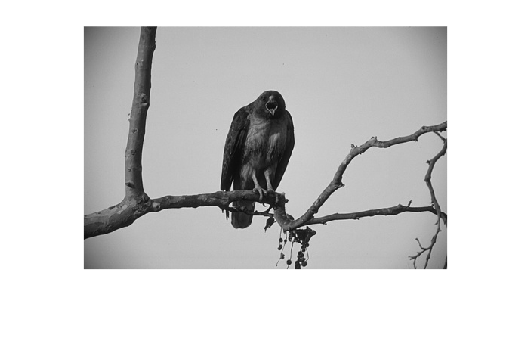

f = imread("imgs\bird.jpg");
g = dip_rgb2gray(f);
imshow(g);

## Test dip_negative

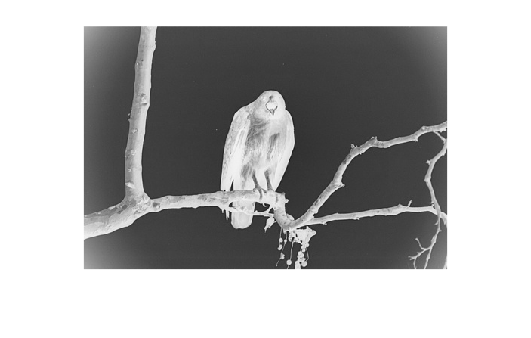

f = imread("imgs\bird.jpg");
g = dip_rgb2gray(f);
g = dip_negative(g);
imshow(g);

## Test dip_chroma

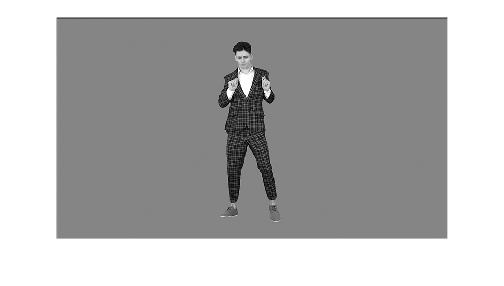

fg = rgb2gray(imread("imgs\foreground.jpg"));
imshow(fg);

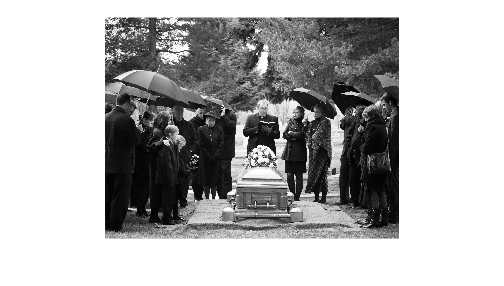

bg = rgb2gray(imread("imgs\background.jpg"));
imshow(bg);

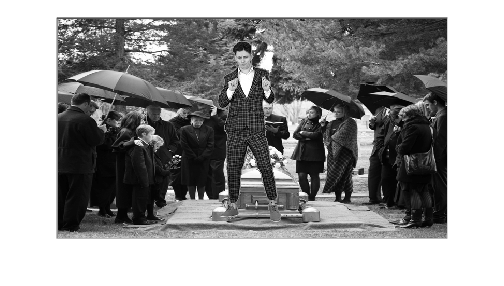

g = dip_chroma(fg, bg, 133); % 3rd argument according to fg's background color
imshow(g);

## Test dip_chroma_color

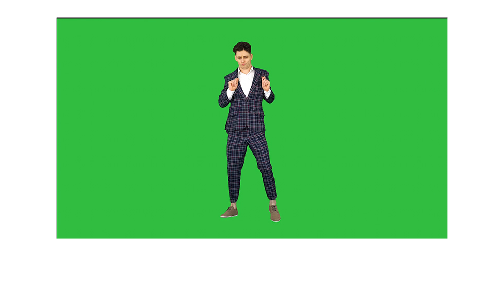

fg = imread("imgs\foreground.jpg");
imshow(fg);

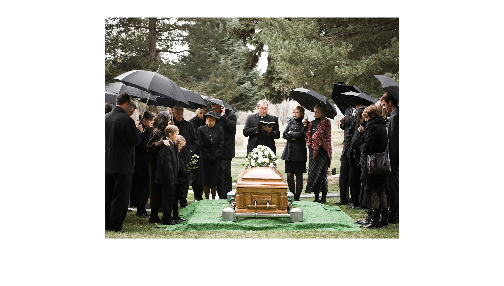

bg = imread("imgs\background.jpg");
imshow(bg);

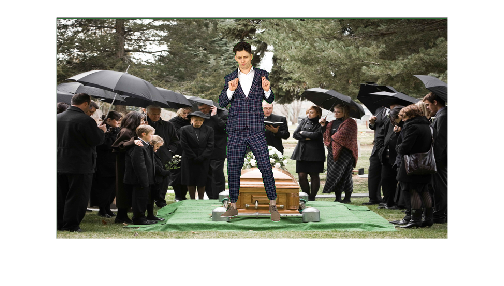

g = dip_color_chroma(fg, bg, [49 189 64], 50); % B's value ([49 189 64]) depends on fg's background color
imshow(g);

## Test dip_diledge

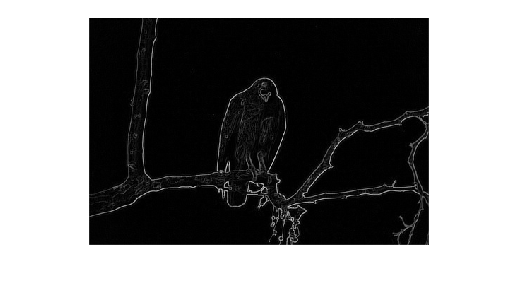

f = rgb2gray(imread("imgs\bird.jpg"));
g = dip_diledge(f, 3);
imshow(g);

## Test dip_blur, dip_sharpen and dip_filtedge

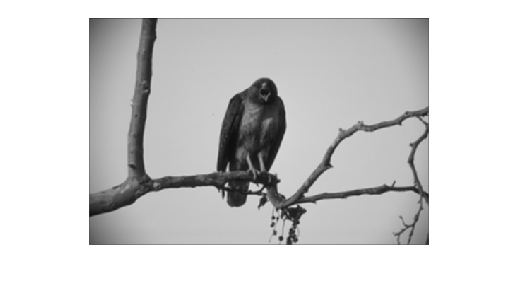

f = rgb2gray(imread("imgs\bird.jpg"));
g = dip_blur(f);
imshow(g);

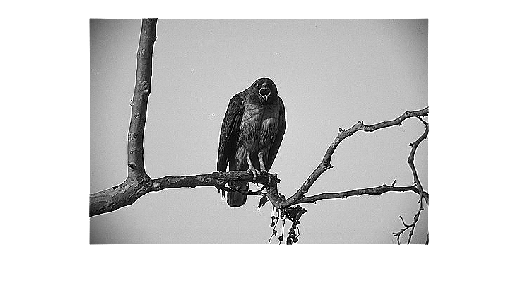

g = dip_sharpen(f);
imshow(g);

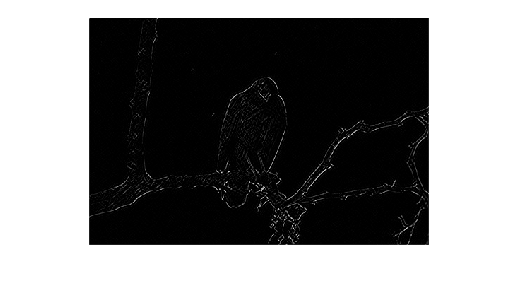

g = dip_edge(f);
imshow(g);

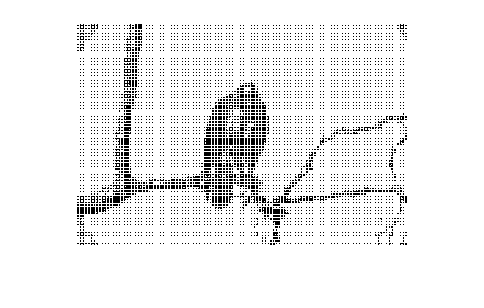

f = rgb2gray(imread("imgs\bird.jpg"));
g = dip_halftone(f, 4);
imshow(g);